# Single Heater: Parameter Estimation

**Objective:** Fit the physics-based predictions to the data as well as fit a first-order plus dead-time (FOPDT) model to the data. In both cases, select parameters are adjusted to minimize an objective function such as a sum of squared errors between the model predicted values and the measured values. Test the temperature response of the Arduino device by introducing a step in the heater.

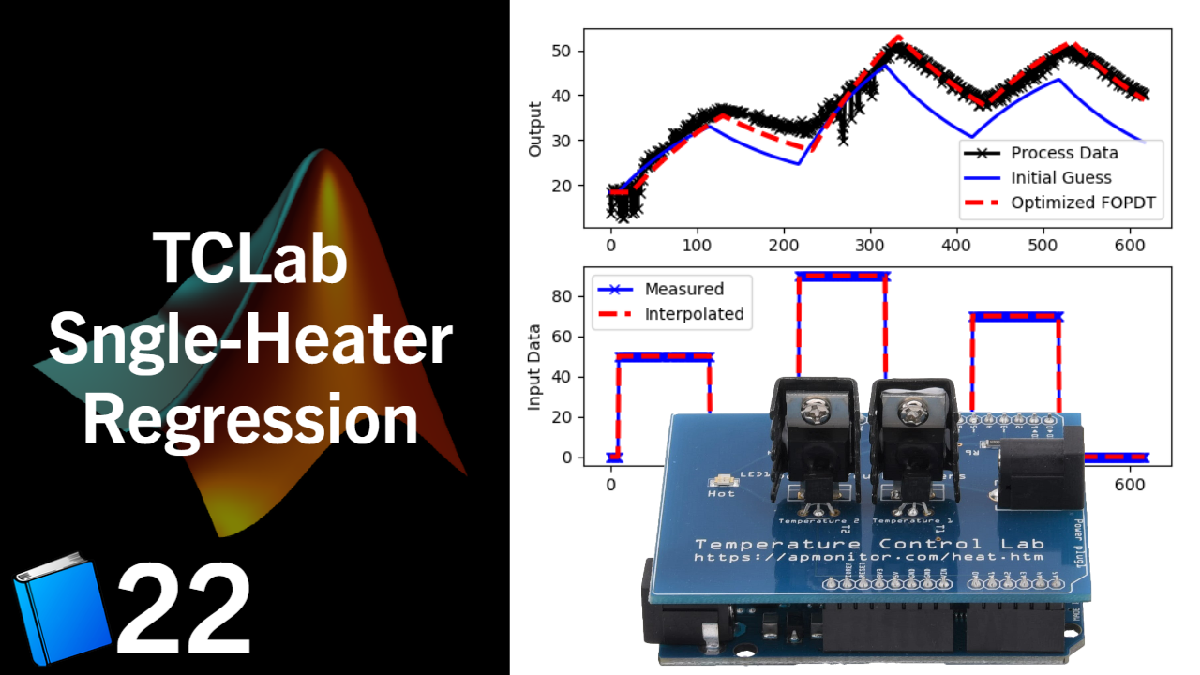

### [View Lecture](https://youtu.be/v6_5QRc9UiI)

## Gather Data

## **Fit FOPDT Model with Optimization**

Determine the parameters of an FOPDT model that best match the dynamic temperature data including $K_p$, $\tau_p$, and $\theta_p$. A second order (SOPDT) can also be fit to investigate whether a higher order model is more accurate.

## **Fit Physics-Based Model with Optimization**

The full energy balance includes convection and radiation terms.


$$m\,c_p\frac{dT}{dt} = U\,A\,\left(T_\infty-T\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T^4\right) + \alpha Q$$


where $m$ is the mass, $c_p$ is the heat capacity, $T$ is the temperature, $U$ is the heat transfer coefficient, $A$ is the area, $T_\infty$ is the ambient temperature, $ \epsilon=0.9$ is the emissivity, $\sigma$ = 5.67x10-8 $W/{m^2 K^4}$ is the Stefan-Boltzmann constant, and $Q$ is the percentage heater output. The parameter $\alpha$ is a factor that relates heater output (0-100%) to power dissipated by the transistor in Watts.

Adjust the uncertain parameters such as $U$ and $\alpha$ from the modeling exercise to best match the dynamic data from the impulse response.

Here, the function `fmincon `performs constrained optimization subject to the constrain that $Ax \le b$. The coefficients of A and b can be configured to create lower and upper bounds for the regressed values.

## **Compare FOPDT and Linearized Model**

A linearized version of the model can be used to compare an FOPDT model to the physics-based model. A linearized model is derived as:


$$m\,c_p\frac{dT}{dt} = f\left(T_\infty,T,V\right) \approx f \left(\bar T_\infty, \bar T, \bar V\right) \ldots \\ + \frac{\partial f}{\partial T_\infty}\bigg|_{\bar T_\infty,\bar T,\bar Q} \left(T_\infty-\bar T_\infty\right) \ldots \\ + \frac{\partial f}{\partial T}\bigg|_{\bar T_\infty,\bar T,\bar Q} \left(T-\bar T\right) \ldots \\ + \frac{\partial f}{\partial V}\bigg|_{\bar T_\infty,\bar T,\bar Q} \left(Q-\bar Q\right)$$


where


$$\frac{\partial f}{\partial T_\infty}\bigg|_{\bar T_\infty,\bar T,\bar Q} = U\,A\,\bar T_\infty + 4\epsilon\,\sigma\,A\,\bar T_\infty^3 = \beta$$



$$\frac{\partial f}{\partial T}\bigg|_{\bar T_\infty,\bar T,\bar Q} = -U\,A\,\bar T - 4\epsilon\,\sigma\,A\,\bar T^3 = \gamma$$



$$\frac{\partial f}{\partial Q}\bigg|_{\bar T_\infty,\bar T,\bar Q} = \alpha$$


The final linearized equation is further simplified by replacing the partial derivatives with constants $\beta$, $\gamma$, and $\alpha$ that are evaluated at the steady state conditions $\bar T_\infty$, $\bar T$, and $\bar Q$.


$$m\,c_p\frac{dT}{dt} = \beta \left(T_\infty-\bar T_\infty\right) + \gamma \left(T-\bar T\right) + \alpha \left(Q-\bar Q\right)$$


This is placed into a time-constant form as by dividing by gamma and substituting the deviation variables $T\prime_\infty = T_\infty -\bar T_\infty$, $T\prime = T -\bar T$, and $Q\prime = Q -\bar Q$.


$$\frac{m\,c_p}{\gamma}\frac{dT^\prime}{dt} = \frac{\beta}{\gamma} T^\prime_\infty + T^\prime + \frac{\alpha}{\gamma} Q^\prime$$


Further simplification is possible with $\beta = -\gamma$.


$$\frac{m\,c_p}{\gamma}\frac{dT^\prime}{dt} = -T^\prime_\infty + T^\prime + \frac{\alpha}{\gamma} Q^\prime$$


Multiplying both sides by *-1* puts the equation into a time constant form with new constants $\tau_P$ and $K_p$.


$$\tau_P \frac{dT^\prime}{dt} = -T^\prime + T^\prime_\infty + K_p Q^\prime$$



$$K_P = -\frac{\alpha}{\gamma}$$



$$\tau_P = -\frac{m\,c_p}{\gamma}$$


This derivation does not include a time delay but the other parameters can be correlated to an empirical FOPDT fit of the data. Another way to fit the uncertain parameters such as overall heat transfer coefficient and $\alpha$ is to use optimization methods. There is a script that demonstrates the use of optimization to minimize an objective function. The objective function is a minimization of the difference between the predicted and measured values.

## **Moving Horizon Estimation**

Sometimes parameters may change over the course of a simulation or control. Moving Horizon Estimation involves real-time regression of unknown parameters while controling a process. Recent data within a specified window is used to regress parameters. Then, the process is controlled based on a model including the regressed parameters.

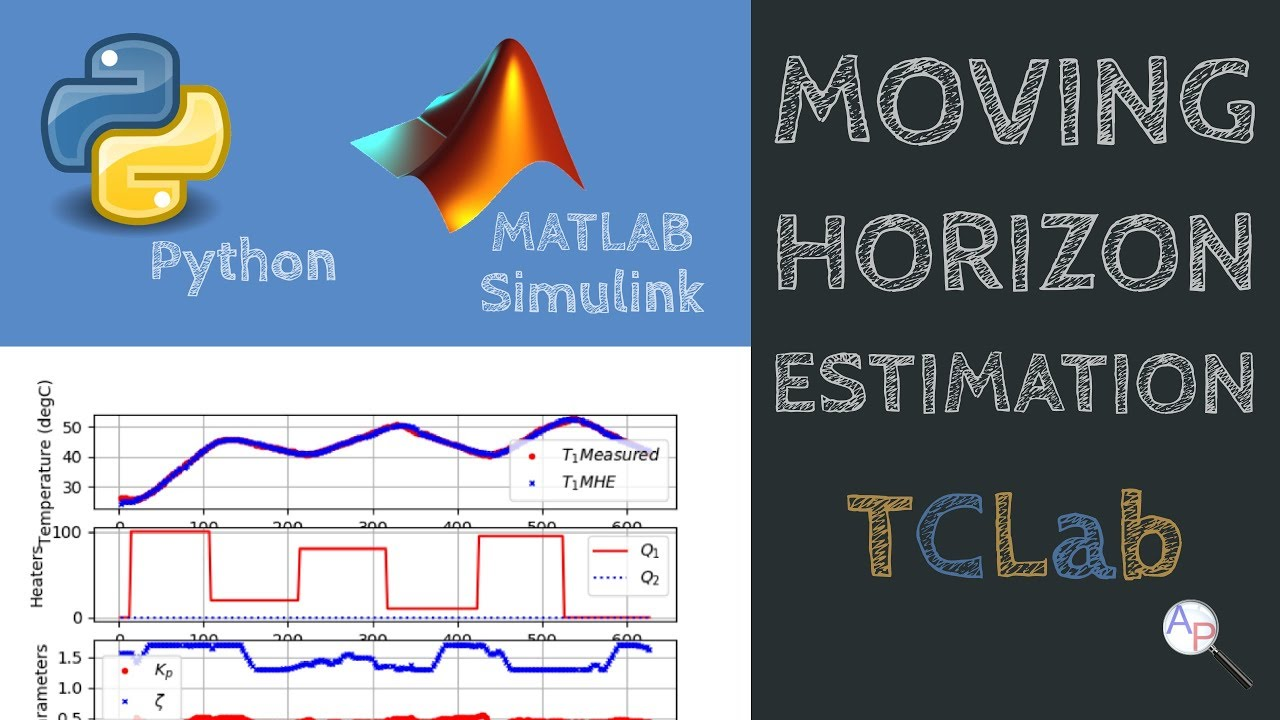

### [View Lecture](https://www.youtube.com/watch?v=Cp6fPUptc74)

function dydt = fopdt(t, y, u, tvals, Km,taum,thetam, yp1, u1)
    % arguments
    %  t      = time
    %  y      = output
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model dead time constant
    %  yp1    = initial output value
    %  u1     = initial input value

    try
        if (t-thetam) <= 0
            um = u1;
        else
            um = interp1(tvals, u, t-thetam);
        end
    catch 
        disp('Error with time extrapolation: ' + t )

        um = u1;
    end
    % calculate derivative
    dydt = (-(y-yp1) + Km * (um-u1))/taum;
end

% simulate FOPDT model with x=[Km,taum,thetam]

function ym = sim_model(x, time_, u_, yp_)
    % input arguments
    Km = x(1);
    taum = x(2);
    thetam = x(3);
    
    ns = length(time_);
    yp1 = yp_(1);
    u1 = u_(1);
    
    % storage for model values
    ym = zeros(ns, 1);  % model
    % initial condition
    ym(1) = yp1;
    % loop through time steps    
    for i = 1:ns-1
        ts = [time_(i),time_(i+1)];
        [~, ys] = ode45(@(t, y) fopdt(t, y, u_, time_, Km,taum,thetam, yp1, u1), ts, ym(i));
        ym(i+1) = ys(end);
    end
end

function obj = objective(x_arg, time_, u_, yProcess)
    % simulate model
    ym = sim_model(x_arg, time_, u_, yProcess); 
    % calculate objective with sum squared error
    obj = sum((ym-yProcess).^2)*1000;
end

function dTdt = heat(~, T, Q, params)
    % unpack unknown parameters
    U = params(1);
    alpha = params(2);
    
    % known parameters
    m = 0.004;  % Kg
    Cp = 500;  % J/kg k
    A = 1.2e-3;  % m^2
    eps = 0.9;
    sigma = 5.67e-8;  % Steffan Boltzman constant
    Ta = 23;
    Tk = T + 273.15;
    Tak = Ta + 273.15; 
    
    dTdt = (1.0/(m*Cp))*(U*A*(Ta-T) ...
                + eps * sigma * A * (Tak^4 - Tk^4) ...
                + alpha*Q);
end

function T_ = sim_energyBalance(params, time_, u_, yp_)

    ns = length(time_);
    
    % storage for model values
    T_ = ones(ns, 1) * 23.0;  % model
    % initial condition
    T_(1) = yp_(1);
    % loop through time steps    
    for i = 1:ns-1
        ts = [time_(i),time_(i+1)];
        [~, ys] = ode45(@(t, y) heat(t, y, u_(i), params), ts, T_(i));
        T_(i+1) = ys(end);
    end
end

function obj = objective_energyBalance(params, time_, u_, yProcess)
    % simulate model
    ym = sim_energyBalance(params, time_, u_, yProcess); 
    % calculate objective with sum squared error
    obj = sum((ym-yProcess).^2)*1000;
end